Download Link [https://github.com/anika-a/EEG-Classification.git](https://github.com/anika-a/EEG-Classification.git)

Control Data has two part (Control_part1 & Control_part2) also ADHD data has two part (ADHD_part1 & ADHD_part2). For ecah of the folder need to run the following code.

clear; clc
addpath("C:\Users\Anika\Desktop\EE 502_Data\ADHD_part1\ADHD_part1\") % Add the path to the folder where the data is saved
path='*.mat';  
files=dir(path);
mkdir('./analysis') % Creating a new folder
mkdir('./analysis1') % creating new folder
for i = 1:length(files) 
    fn = files(i).folder + "/" + files(i).name;
   signal=struct2array(load(fn));
    for h=1:1:width(signal)
        Fs = 128; % Sampling frequency
        T = 1/Fs; % Sampling period
        L = length(signal(:,1)); % Length of signal ['v1p(:,1)' just first coloum]
        time = L*T;
        t = (0:L-1)*T; % Time vector
        figure(1)
        subplot(3,2,1)
        plot(Fs*t(1:L),signal)
         title('Original EEG Signal(19 channels)')
        xlabel('Number of Samples')
        ylabel('X(t)')
        axis ([0 L -inf inf])
        subplot(3,2,2)
        plot(Fs*t(1:L),signal(1:L,1))
        title('Original EEG Signal (single channel)')
        xlabel('Number of Samples')
        ylabel('X(t)')
        axis ([0 L -inf inf])

Filtering 

        Fh1 = 0.5/(Fs/2);
        Fl1 = 62/(Fs/2);
        Fh=49/(Fs/2);
        Fl=51/(Fs/2);
        [b1,a1] = butter(4,[Fh1, Fl1]);
        signal_filtered1 = filtfilt(b1,a1,signal); %Butterworth Filter
        [b,a] = butter(4,[Fh, Fl],'stop'); 
        signal_filtered = filtfilt(b,a,signal_filtered1); %Notch filter
        signal_feq_filtered = fft(signal_filtered);  %Convert to frequency domain
        subplot(3,2,3)
        plot(Fs*t(1:L), signal_filtered)
        title('Time spectrum of the filtered EEG signal(19 channel)')
        xlabel('Time (s)')
        ylabel('Amplitude (\muV)')
        subplot(3,2,4)
        plot(Fs*t(1:L), signal_filtered(1:L,1))
        title('Time spectrum of the filtered EEG signal(single channel)')
        xlabel('Time (s)')
        ylabel('Amplitude (\muV)')
        p2=abs(signal_feq_filtered/L);
        p1=p2(1:floor(L/2+1));
        p1(2:end-1)=2*p1(2:end-1);
        f=Fs*(0:(L/2))/L;
        subplot(3,2,5)
        plot(f, p1)
        title('Frequency spectrum of the filtered EEG signal')
        xlabel('Frequency (Hz)')
        ylabel('Energy (\muV)')

Five frequency band

        h1 = 0.5/(Fs/2);                % High-pass frequency
        l1 = 4/(Fs/2);                  % Low-pass frequency
        [db,da] = butter(2,[h1, l1]);   % Delta band filter

        h2 = 4/(Fs/2);                  % High-pass frequency
        l2 = 8/(Fs/2);                  % Low-pass frequency
        [tb,ta] = butter(4,[h2, l2]);   % Theta band filter

        h3 = 8/(Fs/2);                  % High-pass frequency
        l3 = 13/(Fs/2);                 % Low-pass frequency
        [ab,aa] = butter(4,[h3, l3]);   % Alpha band filter

        h4 = 13/(Fs/2);                 % High-pass frequency
        l4 = 26/(Fs/2);                 % Low-pass frequency
        [bb,ba] = butter(4,[h4, l4]);   % Beta band filter

        h5 = 26/(Fs/2);                 % High-pass frequency
        l5 = 62/(Fs/2);                 % Low-pass frequency
        [gb,ga] = butter(4,[h5, l5]);   % Gamma band filter


        %% Apply frequency band filter on EEG data

        eeg_delta = filtfilt(db,da,signal_filtered);  % Extract delta band
        eeg_theta = filtfilt(tb,ta,signal_filtered);  % Extract theta band
        eeg_alpha = filtfilt(ab,aa,signal_filtered);  % Extract alpha band
        eeg_beta  = filtfilt(bb,ba,signal_filtered);  % Extract beta band
        eeg_gamma = filtfilt(gb,ga,signal_filtered);  % Extract gamma band

        eeg_feq_delta = fft(eeg_delta); % Convert to frequency domain
        eeg_feq_theta = fft(eeg_theta); % Convert to frequency domain
        eeg_feq_alpha = fft(eeg_alpha); % Convert to frequency domain
        eeg_feq_beta  = fft(eeg_beta); % Convert to frequency domain
        eeg_feq_gamma = fft(eeg_gamma);% Convert to frequency domain

        figure(2)
        subplot(5,1,1)
        plot(t, eeg_delta)
        title('Delta Band')
        xlabel('Time (s)'),ylabel('Amplitude (\muV)')
        xlim([0 10]);

        subplot(5,1,2)
        plot(t, eeg_theta)
        title('Theta Band')
        xlabel('Time (s)'),ylabel('Amplitude (\muV)')
        xlim([0 10]);

        subplot(5,1,3)
        plot(t, eeg_alpha)
        title('Alpha Band')
        xlabel('Time (s)'),ylabel('Amplitude (\muV)')
        xlim([0 10]);

        subplot(5,1,4)
        plot(t, eeg_beta)
        title('Beta Band')
        xlabel('Time (s)'),ylabel('Amplitude (\muV)')
        xlim([0 10]);

        subplot(5,1,5)
        plot(t, eeg_gamma)
        title('Gamma Band')
        xlabel('Time (s)'),ylabel('Amplitude (\muV)')
        xlim([0 10]);

Windowing

        w_size = Fs * 2 ;          % The number of samples per 2s segment
        overlap = w_size/2;         % Create a 50% overlap
        n_win =floor(L/128 - 1);    % Number of windows per channel

Features

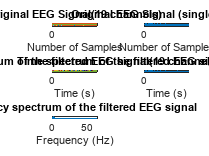

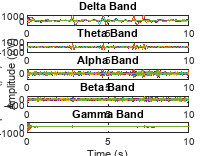

        fea1 = zeros(n_win,19); 
        fea2 = zeros(n_win,19); 
        fea3 = zeros(n_win,19); 
        fea4 = zeros(n_win,19); 
        fea5 = zeros(n_win,19); 
        fea6 = zeros(n_win,19); 
        fea7 = zeros(n_win,19); 
        fea8 = zeros(n_win,19); 
        fea9 = zeros(n_win,19); 
        fea10 = zeros(n_win,19); 
        fea11 = zeros(n_win,19); 
        fea12 = zeros(n_win,19); 
        fea13 = zeros(n_win,19); 
        fea14 = zeros(n_win,19); 

        w_start = 1;                % Start at the first sample
        w_end = w_size;             % End at window length

        for n = 1:n_win
            fea1(n, :) = var(signal_filtered(w_start:w_end, :)); % variance
            fea2(n, :) = mean(signal_filtered(w_start:w_end, :)); % Average 
            fea3(n, :) = std(signal_filtered(w_start:w_end, :));  % Standard Deviation 
            fea4(n, :) = mean(abs(signal_filtered(w_start:w_end, :))); % Mean Absolute Value 
            fea5(n, :) = rms(signal_filtered(w_start:w_end, :));   % Root Mean Square 
            fea6(n, :) = skewness(signal_filtered(w_start:w_end, :)); % Skewness 
            fea7(n, :) = kurtosis(signal_filtered(w_start:w_end, :)); % Kurtosis 
            fea8(n, :) = var(abs(signal_feq_filtered(w_start:w_end, :))); % Average 
            fea9(n, :) = kurtosis(abs(signal_feq_filtered(w_start:w_end, :)));  % Kurtosis FFT
            fea10(n, :)  = jfeeg ('ha', signal_filtered(w_start:w_end, :)); %Hjorth Activity
            fea11(n, :)  = jfeeg ('hm', signal_filtered(w_start:w_end, :)); %Hjorth Mobility
            fea12(n, :)  = jfeeg ('hc', signal_filtered(w_start:w_end, :)); %Hjorth Complexity
            fea13(n, :) = wentropy(signal_filtered(w_start:w_end, :), 'shannon');  % Shannon's Entropy 
            fea14(n, :) = wentropy(abs(signal_feq_filtered(w_start:w_end, :)), 'shannon');   % Spectral Entropy 
            w_start = w_start + overlap;        
            w_end = w_start + w_size;   
        end
        fea = [fea1 fea2 fea3 fea4 fea5 fea6 fea7 fea8 fea9 fea10 fea11 fea12 fea13 fea14];
   
% delta band
        feat1 = zeros(n_win,19); 
        feat2 = zeros(n_win,19); 
        feat3 = zeros(n_win,19); 
        feat4 = zeros(n_win,19); 
        feat5 = zeros(n_win,19); 
        feat6 = zeros(n_win,19); 
        feat7 = zeros(n_win,19); 
        feat8 = zeros(n_win,19); 
        feat9 = zeros(n_win,19); 
        feat10 = zeros(n_win,19); 
        feat11 = zeros(n_win,19); 
        feat12 = zeros(n_win,19); 
        feat13 = zeros(n_win,19); 
        feat14 = zeros(n_win,19); 

        w_start = 1;                % Start at the first sample
        w_end = w_size;             % End at window length

        for n = 1:n_win
            feat1(n, :) = var(eeg_delta(w_start:w_end, :)); % variance
            feat2(n, :) = mean(eeg_delta(w_start:w_end, :)); % Average 
            feat3(n, :) = std(eeg_delta(w_start:w_end, :));  % Standard Deviation 
            feat4(n, :) = mean(abs(eeg_delta(w_start:w_end, :))); % Mean Absolute Value 
            feat5(n, :) = rms(eeg_delta(w_start:w_end, :));   % Root Mean Square 
            feat6(n, :) = skewness(eeg_delta(w_start:w_end, :)); % Skewness 
            feat7(n, :) = kurtosis(eeg_delta(w_start:w_end, :)); % Kurtosis 
            feat8(n, :) = var(abs(eeg_feq_delta(w_start:w_end, :))); % Average 
            feat9(n, :) = kurtosis(abs(eeg_feq_delta(w_start:w_end, :)));  % Kurtosis 
            feat10(n, :)  = jfeeg ('ha', eeg_delta(w_start:w_end, :));
            feat11(n, :)  = jfeeg ('hm', eeg_delta(w_start:w_end, :));
            feat12(n, :)  = jfeeg ('hc', eeg_delta(w_start:w_end, :));
            feat13(n, :) = wentropy(eeg_delta(w_start:w_end, :), 'shannon');  % Shannon's Entropy 
            feat14(n, :) = wentropy(abs(eeg_feq_delta(w_start:w_end, :)), 'shannon');   % Spectral Entropy 
            w_start = w_start + overlap;        
            w_end = w_start + w_size;   
        end
        fea_delta = [feat1 feat2 feat3 feat4 feat5 feat6 feat7 feat8 feat9 feat10 feat11 feat12 feat13 feat14];
        
        clearvars n feat1 feat2 feat3 feat4 feat5 feat6 feat7 feat8 feat9 feat10 feat11 feat12 feat13 feat14
        %theta band
        feat1 = zeros(n_win,19); 
        feat2 = zeros(n_win,19); 
        feat3 = zeros(n_win,19); 
        feat4 = zeros(n_win,19); 
        feat5 = zeros(n_win,19); 
        feat6 = zeros(n_win,19); 
        feat7 = zeros(n_win,19); 
        feat8 = zeros(n_win,19); 
        feat9 = zeros(n_win,19); 
        feat10 = zeros(n_win,19); 
        feat11 = zeros(n_win,19); 
        feat12 = zeros(n_win,19); 
        feat13 = zeros(n_win,19); 
        feat14 = zeros(n_win,19); 

        w_start = 1;                % Start at the first sample
        w_end = w_size;             % End at window length

        for n = 1:n_win
            feat1(n, :) = var(eeg_theta(w_start:w_end, :)); % variance
            feat2(n, :) = mean(eeg_theta(w_start:w_end, :)); % Average 
            feat3(n, :) = std(eeg_theta(w_start:w_end, :));  % Standard Deviation 
            feat4(n, :) = mean(abs(eeg_theta(w_start:w_end, :))); % Mean Absolute Value 
            feat5(n, :) = rms(eeg_theta(w_start:w_end, :));   % Root Mean Square 
            feat6(n, :) = skewness(eeg_theta(w_start:w_end, :)); % Skewness 
            feat7(n, :) = kurtosis(eeg_theta(w_start:w_end, :)); % Kurtosis 
            feat8(n, :) = var(abs(eeg_feq_theta(w_start:w_end, :))); % Average 
            feat9(n, :) = kurtosis(abs(eeg_feq_theta(w_start:w_end, :)));  % Kurtosis 
            feat10(n, :)  = jfeeg ('ha', eeg_theta(w_start:w_end, :));
            feat11(n, :)  = jfeeg ('hm', eeg_theta(w_start:w_end, :));
            feat12(n, :)  = jfeeg ('hc', eeg_theta(w_start:w_end, :));
            feat13(n, :) = wentropy(eeg_theta(w_start:w_end, :), 'shannon');  % Shannon's Entropy 
            feat14(n, :) = wentropy(abs(eeg_feq_theta(w_start:w_end, :)), 'shannon');   % Spectral Entropy 
            w_start = w_start + overlap;        
            w_end = w_start + w_size;   
        end
        fea_theta = [feat1 feat2 feat3 feat4 feat5 feat6 feat7 feat8 feat9 feat10 feat11 feat12 feat13 feat14];
        
        clearvars n feat1 feat2 feat3 feat4 feat5 feat6 feat7 feat8 feat9 feat10 feat11 feat12 feat13 feat14
        % Alpha band
        feat1 = zeros(n_win,19); 
        feat2 = zeros(n_win,19); 
        feat3 = zeros(n_win,19); 
        feat4 = zeros(n_win,19); 
        feat5 = zeros(n_win,19); 
        feat6 = zeros(n_win,19); 
        feat7 = zeros(n_win,19); 
        feat8 = zeros(n_win,19); 
        feat9 = zeros(n_win,19); 
        feat10 = zeros(n_win,19); 
        feat11 = zeros(n_win,19); 
        feat12 = zeros(n_win,19); 
        feat13 = zeros(n_win,19); 
        feat14 = zeros(n_win,19); 

        w_start = 1;                % Start at the first sample
        w_end = w_size;             % End at window length

        for n = 1:n_win
            feat1(n, :) = var(eeg_alpha(w_start:w_end, :)); % variance
            feat2(n, :) = mean(eeg_alpha(w_start:w_end, :)); % Average 
            feat3(n, :) = std(eeg_alpha(w_start:w_end, :));  % Standard Deviation 
            feat4(n, :) = mean(abs(eeg_alpha(w_start:w_end, :))); % Mean Absolute Value 
            feat5(n, :) = rms(eeg_alpha(w_start:w_end, :));   % Root Mean Square 
            feat6(n, :) = skewness(eeg_alpha(w_start:w_end, :)); % Skewness 
            feat7(n, :) = kurtosis(eeg_alpha(w_start:w_end, :)); % Kurtosis 
            feat8(n, :) = var(abs(eeg_feq_alpha(w_start:w_end, :))); % Average 
            feat9(n, :) = kurtosis(abs(eeg_feq_alpha(w_start:w_end, :)));  % Kurtosis 
            feat10(n, :)  = jfeeg ('ha', eeg_alpha(w_start:w_end, :));
            feat11(n, :)  = jfeeg ('hm', eeg_alpha(w_start:w_end, :));
            feat12(n, :)  = jfeeg ('hc', eeg_alpha(w_start:w_end, :));
            feat13(n, :) = wentropy(eeg_alpha(w_start:w_end, :), 'shannon');  % Shannon's Entropy 
            feat14(n, :) = wentropy(abs(eeg_feq_alpha(w_start:w_end, :)), 'shannon');   % Spectral Entropy 
            w_start = w_start + overlap;        
            w_end = w_start + w_size;   
        end
        fea_alpha = [feat1 feat2 feat3 feat4 feat5 feat6 feat7 feat8 feat9 feat10 feat11 feat12 feat13 feat14];
        
        clearvars n feat1 feat2 feat3 feat4 feat5 feat6 feat7 feat8 feat9 feat10 feat11 feat12 feat13 feat14
        %Beta band
        feat1 = zeros(n_win,19); 
        feat2 = zeros(n_win,19); 
        feat3 = zeros(n_win,19); 
        feat4 = zeros(n_win,19); 
        feat5 = zeros(n_win,19); 
        feat6 = zeros(n_win,19); 
        feat7 = zeros(n_win,19); 
        feat8 = zeros(n_win,19); 
        feat9 = zeros(n_win,19); 
        feat10 = zeros(n_win,19); 
        feat11 = zeros(n_win,19); 
        feat12 = zeros(n_win,19); 
        feat13 = zeros(n_win,19); 
        feat14 = zeros(n_win,19); 

        w_start = 1;                % Start at the first sample
        w_end = w_size;             % End at window length

        for n = 1:n_win
            feat1(n, :) = var(eeg_beta(w_start:w_end, :)); % variance
            feat2(n, :) = mean(eeg_beta(w_start:w_end, :)); % Average 
            feat3(n, :) = std(eeg_beta(w_start:w_end, :));  % Standard Deviation 
            feat4(n, :) = mean(abs(eeg_beta(w_start:w_end, :))); % Mean Absolute Value 
            feat5(n, :) = rms(eeg_beta(w_start:w_end, :));   % Root Mean Square 
            feat6(n, :) = skewness(eeg_beta(w_start:w_end, :)); % Skewness 
            feat7(n, :) = kurtosis(eeg_beta(w_start:w_end, :)); % Kurtosis 
            feat8(n, :) = var(abs(eeg_feq_beta(w_start:w_end, :))); % Average 
            feat9(n, :) = kurtosis(abs(eeg_feq_beta(w_start:w_end, :)));  % Kurtosis 
            feat10(n, :)  = jfeeg ('ha', eeg_beta(w_start:w_end, :));
            feat11(n, :)  = jfeeg ('hm', eeg_beta(w_start:w_end, :));
            feat12(n, :)  = jfeeg ('hc', eeg_beta(w_start:w_end, :));
            feat13(n, :) = wentropy(eeg_beta(w_start:w_end, :), 'shannon');  % Shannon's Entropy 
            feat14(n, :) = wentropy(abs(eeg_feq_beta(w_start:w_end, :)), 'shannon');   % Spectral Entropy 
            w_start = w_start + overlap;        
            w_end = w_start + w_size;   
        end
        fea_beta = [feat1 feat2 feat3 feat4 feat5 feat6 feat7 feat8 feat9 feat10 feat11 feat12 feat13 feat14];
        
        clearvars n feat1 feat2 feat3 feat4 feat5 feat6 feat7 feat8 feat9 feat10 feat11 feat12 feat13 feat14

         %gamma band
        feat1 = zeros(n_win,19); 
        feat2 = zeros(n_win,19); 
        feat3 = zeros(n_win,19); 
        feat4 = zeros(n_win,19); 
        feat5 = zeros(n_win,19); 
        feat6 = zeros(n_win,19); 
        feat7 = zeros(n_win,19); 
        feat8 = zeros(n_win,19); 
        feat9 = zeros(n_win,19); 
        feat10 = zeros(n_win,19); 
        feat11 = zeros(n_win,19); 
        feat12 = zeros(n_win,19); 
        feat13 = zeros(n_win,19); 
        feat14 = zeros(n_win,19); 

        w_start = 1;                % Start at the first sample
        w_end = w_size;             % End at window length

        for n = 1:n_win
            feat1(n, :) = var(eeg_gamma(w_start:w_end, :)); % variance
            feat2(n, :) = mean(eeg_gamma(w_start:w_end, :)); % Average 
            feat3(n, :) = std(eeg_gamma(w_start:w_end, :));  % Standard Deviation 
            feat4(n, :) = mean(abs(eeg_gamma(w_start:w_end, :))); % Mean Absolute Value 
            feat5(n, :) = rms(eeg_gamma(w_start:w_end, :));   % Root Mean Square 
            feat6(n, :) = skewness(eeg_gamma(w_start:w_end, :)); % Skewness 
            feat7(n, :) = kurtosis(eeg_gamma(w_start:w_end, :)); % Kurtosis 
            feat8(n, :) = var(abs(eeg_feq_gamma(w_start:w_end, :))); % Average 
            feat9(n, :) = kurtosis(abs(eeg_feq_gamma(w_start:w_end, :)));  % Kurtosis 
            feat10(n, :)  = jfeeg ('ha', eeg_gamma(w_start:w_end, :));
            feat11(n, :)  = jfeeg ('hm', eeg_gamma(w_start:w_end, :));
            feat12(n, :)  = jfeeg ('hc', eeg_gamma(w_start:w_end, :));
            feat13(n, :) = wentropy(eeg_gamma(w_start:w_end, :), 'shannon');  % Shannon's Entropy 
            feat14(n, :) = wentropy(abs(eeg_feq_gamma(w_start:w_end, :)), 'shannon');   % Spectral Entropy 
            w_start = w_start + overlap;        
            w_end = w_start + w_size;   
        end
        fea_gamma = [feat1 feat2 feat3 feat4 feat5 feat6 feat7 feat8 feat9 feat10 feat11 feat12 feat13 feat14];
        
        clearvars n feat1 feat2 feat3 feat4 feat5 feat6 feat7 feat8 feat9 feat10 feat11 feat12 feat13 feat14
    
    end
    f1= [fea fea_delta fea_theta fea_alpha fea_beta fea_gamma];
    f2= [fea_delta fea_theta fea_beta];
    save("./analysis/" + files(i).name, 'f1') % Saving each participants data in analysis folder
    save("./analysis1/" + files(i).name, 'f2') % Saving each participants three frequency Band data in analysis1 folder
    clear f1;
    clear f2;
end